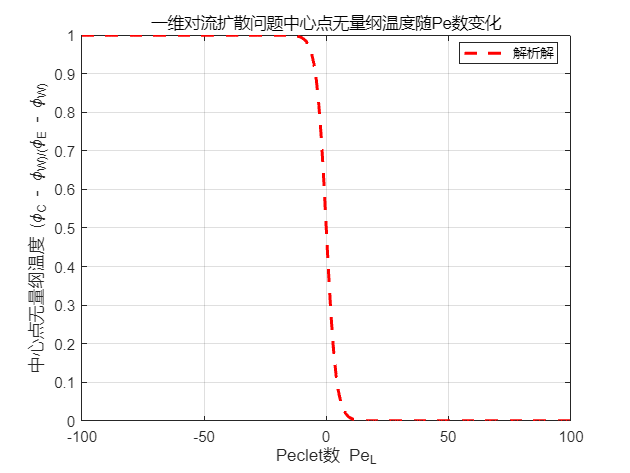

% 在程序开始时关闭警告
warning('off', 'MATLAB:structOnObject');
clear; clc; close all;
time_begin = tic;

dim = 2;

ncx = 3; % 奇数，确保有中心单元
ncy = 1;  % y方向1个单元（一维问题）
ncz = 1;  % z方向1个单元

% 计算域范围调整为 [0,1] 以匹配解析解
xmin = 0;
xmax = 1;
ymin = 0;
ymax = 1;
zmin = 0;
zmax = 1;

% 定义要扫描的Peclet数范围
Pe_L_values = -10:1:10; % 从-10到10
center_dimensionless_temps = zeros(size(Pe_L_values)); % 存储中心点无量纲温度

% 对不同Pe数进行扫描
nsteps = 1e3;
res_freq = 1e3;
out_freq = 5e3;
niter_t = 20; relax_t = 0.9; 
res_t = 1e-2;
temp_tol = 1e-4;
con_val = 1.0; % 固定导热系数
dens = 1.0; mu = 1e-3; spheat_val = 0.0; % 比热设为0，稳态问题

%% 计算解析解
figure;
analytical_dimensionless_temps = zeros(size(Pe_L_values));
for i = 1:length(Pe_L_values)
    Pe_L = Pe_L_values(i);
    if Pe_L == 0
        % 纯扩散情况：线性分布，中心点无量纲温度为0.5
        analytical_dimensionless_temps(i) = 0.5;
    else
        % 一维对流扩散解析解：T(x) = (exp(Pe_L*x) - 1) / (exp(Pe_L) - 1)
        % 计算 (φ_C - φ_W)/(φ_E - φ_W)
        x_C = 0.5; % 中心点位置
        x_W = 0.5 - 1/(ncx-1); % 西侧相邻点位置
        x_E = 0.5 + 1/(ncx-1); % 东侧相邻点位置
        
        phi_C = (exp(Pe_L*x_C) - 1) / (exp(Pe_L) - 1);
        phi_W = (exp(Pe_L*x_W) - 1) / (exp(Pe_L) - 1);
        phi_E = (exp(Pe_L*x_E) - 1) / (exp(Pe_L) - 1);
        
        analytical_dimensionless_temps(i) = (phi_C - phi_W) / (phi_E - phi_W);
    end
end
plot(Pe_L_values, analytical_dimensionless_temps, 'r--', 'LineWidth', 2, 'DisplayName', '解析解');
hold on;

% 设置对流格式 - 'centraldifference'或'upwind'
for scheme_num = 1:2
    switch scheme_num
        case 1
            scheme_name = 'centraldifference';
            line_style = 'bo-';
        case 2
            scheme_name = 'upwind';
            line_style = 'gs-';
    end

    for pe_idx = 1:length(Pe_L_values)
        Pe_L = Pe_L_values(pe_idx);
        
        % 根据Pe数计算导热系数和流速
        if Pe_L == 0
            u_val = 0.0; % 纯扩散情况
        else
            u_val = Pe_L * con_val; % u = Pe_L * Γ (因为ρ=1, L=1)
        end

        fprintf('\n=== 正在计算 Pe_L = %.1f (u = %.3f, con = %.3f) ===\n', Pe_L, u_val, con_val);
        
        % 创建网格对象
        mesh = structured_mesh();
        mesh = mesh.create_mesh(dim, ncx, ncy, ncz, xmin, xmax, ymin, ymax, zmin, zmax);
    
        T = 0.5; % 初始条件设为0.5
        mesh = mesh.set_initial_t(T);
        mesh = mesh.create_field_data();
        mesh = mesh.create_coefficient_data(); 
        mesh = mesh.set_scheme(scheme_name);  
        
        % 设置面速度场 - 根据Pe数符号设置流速方向
        mesh = mesh.set_uniform_face_velocity(u_val, 0.0, 0.0);
        mesh = mesh.set_nsteps(nsteps);
        mesh = mesh.set_temperature_solver_param(niter_t, relax_t, res_t, temp_tol);
    
        fluid_properties = fluid_properties(mesh);
        fluid_properties = fluid_properties.set_initial_fluid(dens, mu, con_val, spheat_val);
    
        boundary = boundary(mesh);
        boundary = boundary.create_faces_of_cells(mesh);
        boundary = boundary.create_boundary_fluid(dim, 'wall', 'wall', 'wall', 'wall', 'wall', 'wall');
        
        % 设置温度边界条件
        boundary = boundary.create_boundary_temp(dim, ...
            'xmin', {'constant', 0.0}, ...    % x=0: T=0
            'xmax', {'constant', 1.0}, ...    % x=1: T=1
            'ymin', {'heatflux', 0.0}, ...    % 绝热
            'ymax', {'heatflux', 0.0}, ...    % 绝热
            'zmin', {'heatflux', 0.0}, ...    % 绝热
            'zmax', {'heatflux', 0.0});       % 绝热
    
        % 创建后处理对象
        post = post_processing();
        post = post.Set_res_out_freq(res_freq, out_freq);
    
        % 开始仿真迭代
        for it = 1:nsteps
            % 调用分离求解器
            [mesh.stop_sim, l2_t_over_l2_max_t] = collocated_segregated.solve(it, mesh, fluid_properties, boundary, post);
                
            % 检查收敛条件
            if mesh.stop_sim
                fprintf('在迭代 %d 收敛\n', it);
                break;
            end
            
            if it == nsteps
                fprintf('达到最大迭代次数 %d\n', it);
            end
        end
    
        % 获取中心点及其相邻点的温度，计算无量纲温度
        center_i = ceil(ncx/2); % 中心单元索引
        west_i = center_i - 1;  % 西侧相邻单元索引
        east_i = center_i + 1;  % 东侧相邻单元索引
        
        phi_C = mesh.t(center_i, 1, 1);
        phi_W = mesh.t(west_i, 1, 1);
        phi_E = mesh.t(east_i, 1, 1);
        
        % 计算无量纲温度 (φ_C - φ_W)/(φ_E - φ_W)
        dimensionless_temp = (phi_C - phi_W) / (phi_E - phi_W);
        center_dimensionless_temps(pe_idx) = dimensionless_temp;
        
        fprintf('Pe_L = %.1f, 中心点无量纲温度 = %.6f\n', Pe_L, dimensionless_temp);
        
        % 清理变量，准备下一次计算
        clear mesh fluid_properties boundary post;
    end

    %% 输出结果并绘图
    fprintf('\n=== %s格式结果汇总 ===\n', scheme_name);
    fprintf('Pe_L\t数值解\t解析解\t误差\n');
    for i = 1:length(Pe_L_values)
        error = abs(center_dimensionless_temps(i) - analytical_dimensionless_temps(i));
        fprintf('%6.1f\t%8.6f\t%8.6f\t%8.6f\n', ...
            Pe_L_values(i), center_dimensionless_temps(i), analytical_dimensionless_temps(i), error);
    end

    % 绘制中心点无量纲温度随Pe数变化
    plot(Pe_L_values, center_dimensionless_temps, line_style, 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', sprintf('%s格式数值解', scheme_name));
end

xlabel('Peclet数 Pe_L');
ylabel('中心点无量纲温度 (\phi_C - \phi_W)/(\phi_E - \phi_W)');
title('一维对流扩散问题中心点无量纲温度随Pe数变化');
legend('Location', 'best');
grid on;


%% 计算总运行时间
total_time = toc(time_begin);
fprintf("总运行时间: %.6f 秒\n", total_time);

总运行时间: 0.185565 秒



fprintf('仿真完成！\n');

仿真完成！



% 在程序结束时恢复警告
warning('on', 'MATLAB:structOnObject');